# **INSTITUTO POLITÉCNICO NACIONAL**

# **UNIDAD PROFESIONAL INTERDISCIPLINARIA DE INGENIERÍA EN TECNOLOGÍAS AVANZADAS**

# Práctica 2: Señales en tiempo discreto

## Materia: Análisis de Señales y Sistemas

## Profesor: Rafael Martínez Martínez

## Integrantes:

## Huerta Sánchez Jesus Alejandro.

## Navarro Herrera Leon Ricardo.

## GRUPO: 2MV1

## Fecha de entrega: 28/02/2020

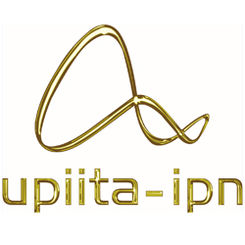                                                  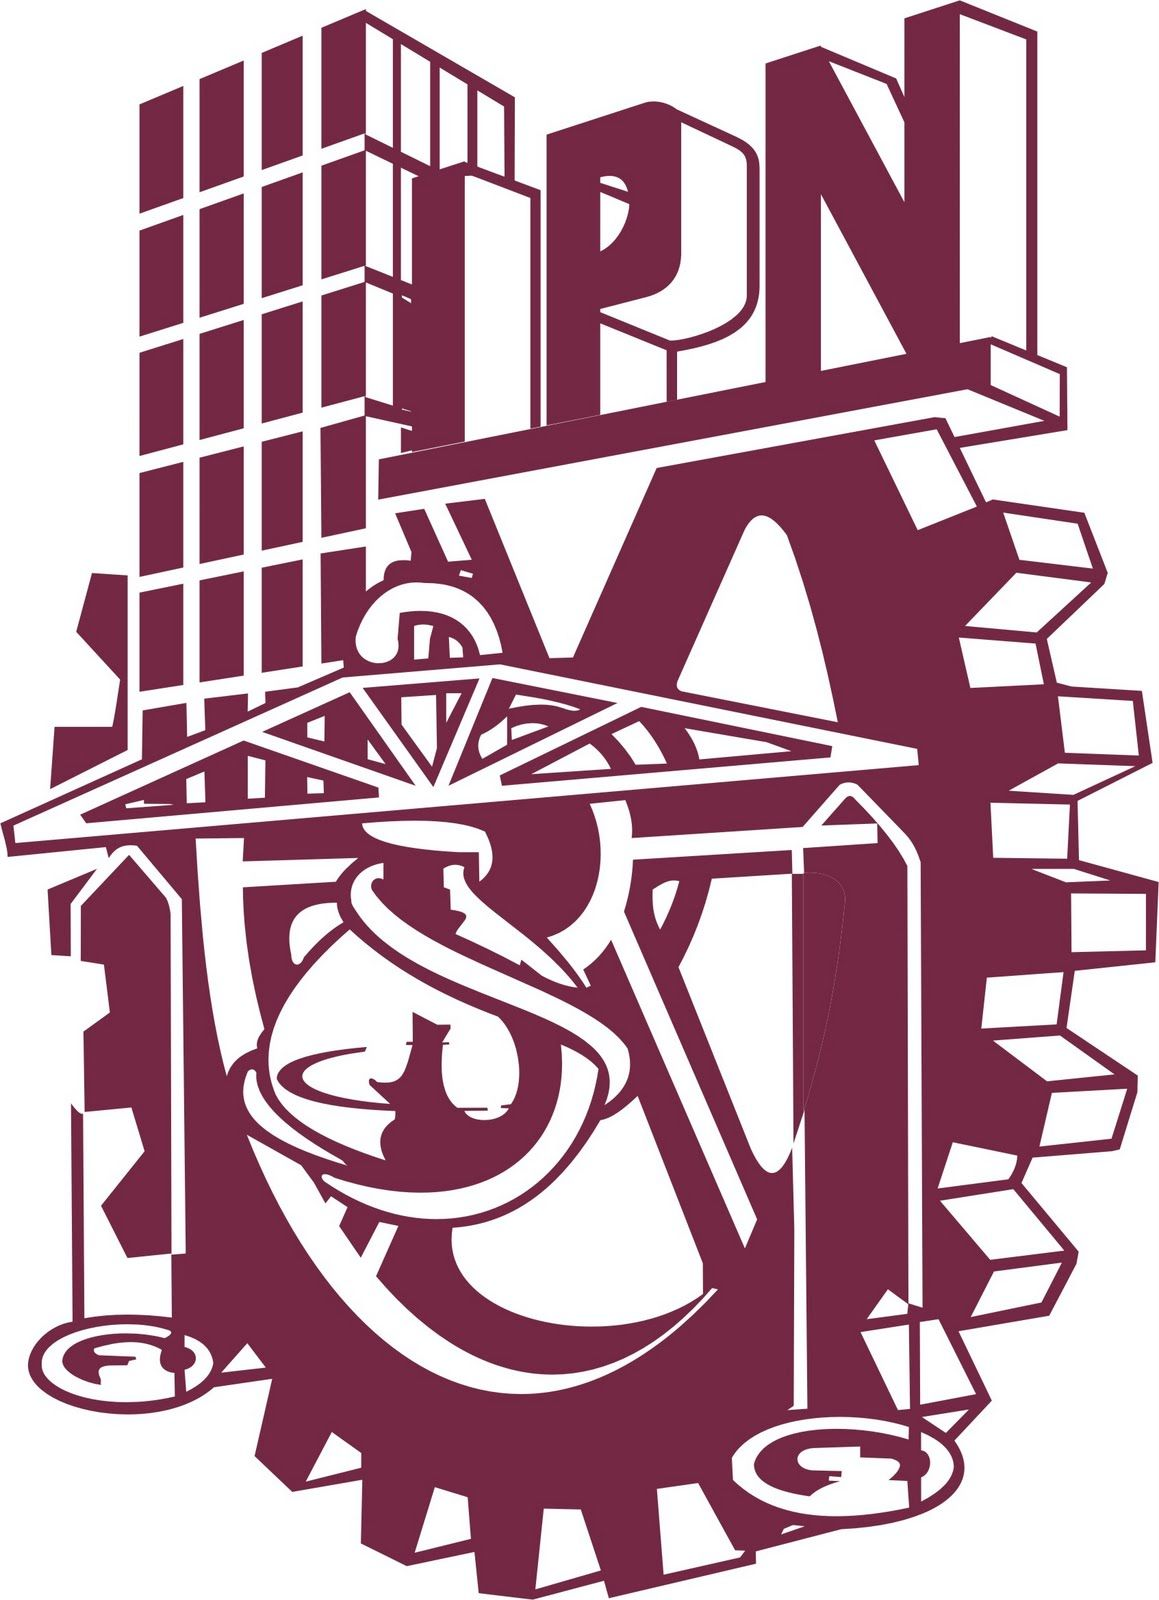

## Objetivos:

- Manipulación básica de MATLAB.

- Gráficas de señales reales y complejas discretas.

- Transformación de señales discretas (escalamientos y traslaciones).

## Introducción:

En la presente práctica se analizará el trato que se debe dar a las funciones en tiempo discreto, cuya definición según la teoría es que son señales con un dominio discreto, este dominio es un conjunto, y los conjuntos de tipo discreto, pueden ser finitos y estar totalmente determinados, o infinitos, y en este caso para diferenciarse de los conjuntos continuos, se conocen como conjuntos discretos infinitos numerables. También podemos decir que la señal en tiempo discreto es una función que tiene cuya variable independiente solo puede tomar el valor de los números enteros, por lo que se puede decir que en cierto sentido, los valores de las señales en tiempo discreto están "separados entre ellos" y que se pueden diferenciar unos de otros.

Se pueden realizar varias operaciones y modificaciones a las señales de este tipo, y la mayoría de estas transformaciones aplican de forma casi igual que como lo hacen en señales en tiempo continuo, revisadas en la práctica anterior, es decir, las traslaciones en tiempo y los escalamientos verticales funcionan igual, pero para señales discretas hay algunos fenómenos interesantes a la hora de realizar escalamientos horizontales, y estos son los que describiremos un poco a continuación:

### Escalamiento horizontal 

Se conoce como escalamiento horizontal de una señal a la expansión o compresión de una señal en el tiempo más apegado a la notación de señales discretas, es un escalamiento de cualquiera de los dos tipos mencionados "en" o "sobre" el eje [n].

La definición como podemos observar es igual sin importar el tipo de señal, ya que aplica de la misma manera para señales en tiempo continuo y discreto, la diferencia real se encuentra en como operan dichos escalamientos en el tiempo discreto: Hay dos fenómenos importantes, cada uno corresponde a un tipo de escalamiento.

### Compresión continuo:

Al comprimir una señal en tiempo continuo, se reduce el tiempo en el que ocurre todo.

#### Ejemplo 1:

Lo anterior se explica considerando por ejemplo comprimir la señal x(t)=t en -2<t<2 en un factor de 2, lo que ocurre es que las alturas se muestran antes, en la mitad del tiempo por el factor que utilizamos, es decir la del 2 pasa al 1, la del 3 al 1.5, etc. Observamos las figuras para corroborar el ejemplo:

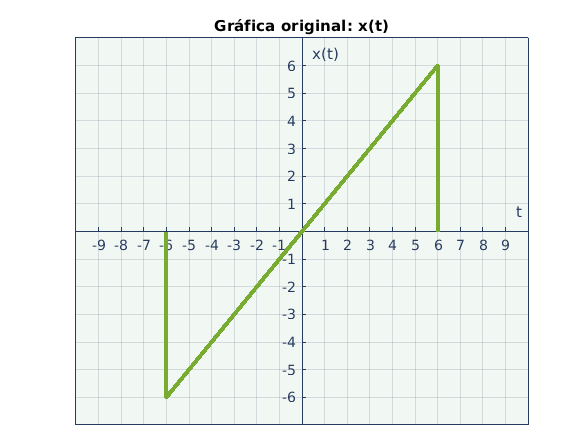

t=-6.01:.01:6.01;
x= @(t) t.*(-6<=t).*(t<=6);
Graficarpr2(t,x(t));
title("Gráfica original: x(t)");

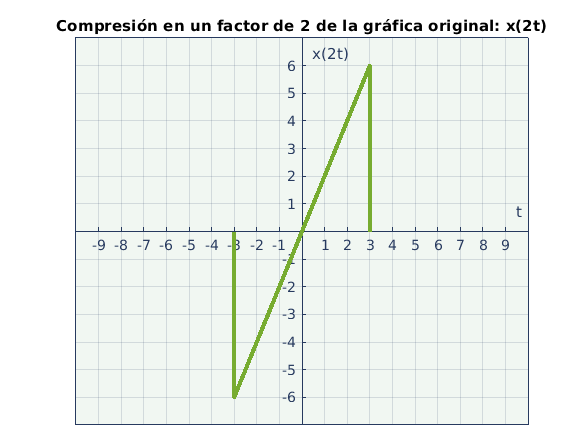

t=-3.01:.01:3.01;
Graficarpr2(t,x(2*t));
title("Compresión en un factor de 2 de la gráfica original: x(2t)");
ylabel("x(2t)");

### Compresión discreto:

Al comprimir una señal en tiempo discreto también reducimos el tiempo en que aparecen los valores de las alturas y de igual forma en otro sentido perdemos información, ya que sólo sobreviven las alturas de los múltiplos de la compresión que realizamos, y si estaba en 2, pasa a 1, en 4 a 2, etc. También observamos que al sólo poder evaluar en enteros, no podemos generar alturas intermedias para los datos que perdemos. Se visualiza mejor lo anterior con un ejemplo.

#### Ejemplo 2:

Consideramos ahora comprimir la señal x[n]=n en -2<n<2 en un factor de 2, observamos que al igual que para tiempo continuo las alturas se muestran en la mitad del tiempo, o lo que es equivalente a decir, solo se toman las alturas de los múltiplos del factor de compresión y se colocan en los valores correspondientes es decir como en el ejemplo, el valor que correspondía a 2 se puso en 1, el de 4 en 2, etc. Pero, aquí nos detenemos un momento porque observamos que las alturas correspondientes en este caso a 3,5,7, etc. desaparecen, ya que sólo podemos evaluar en enteros y al hacer la compresión dichas alturas son simplemente "borradas", lo que en la realidad provocaría una perdida de información, a este fenómeno se le llama diezmar y consiste en conservar sólo las enésimas muestras de señales determinadas "omitiendo" las demás, y se observa claramentre este fenómeno en la segunda gráfica.

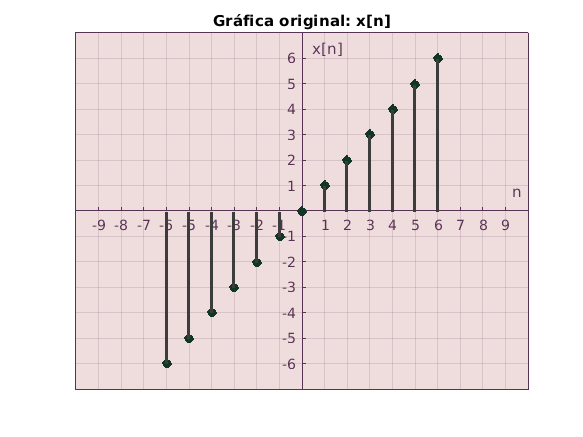

n=[-6.01:1:6.01];
x= @(n) n.*(n>=-7).*(n<=6);
Graficarpr1(n,x(n));
title("Gráfica original: x[n]");

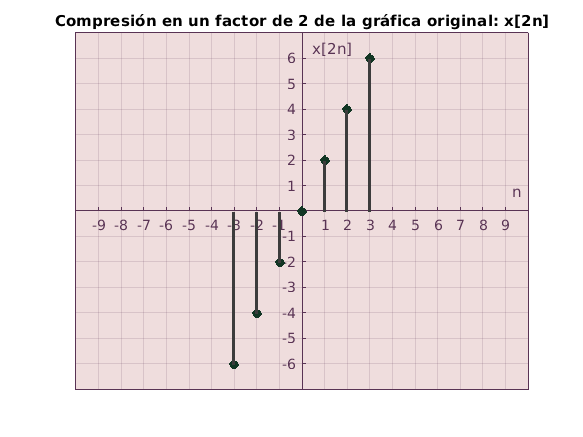

n=[-3.01:1:3.01];
Graficarpr1(n,x(2*n));
title("Compresión en un factor de 2 de la gráfica original: x[2n]");
ylabel("x[2n]");

Como se observa, solo quedaron 6 datos (muestras) y los otros 6 que si estaban en la señal original se perdieron, este es un problema real en la transmición de información pero también se ve como una ventaja, ya que al comprimir señales muy grandes se ahorra espacio y muchos algoritmos modernos ya permiten recuperarla bastante fielmente o incluso reconstruir lo que se pretendía transmitir sin necesidad de recuperar toda la señal.

### Expansión continuo:

Al expandir una señal en tiempo continuo, de alguna manera aumentamos el tiempo en que los eventos se presentan, o en otras palabras, estiramos la señal en el tiempo. Veamos el ejemplo:

#### Ejemplo 1:

Empleando ahora una señal diferente, sea x(t)= t^3 en -2<t<2 si realizamos una expansión horizontal por un factor de 2, obtenemos una gráfica donde las alturas de cada punto se van para este caso al siguiente múltiplo de 2, es decir, 1 a 2, 2 a 4, 3 a 6, 4 a 8, etc. observamos las siguientes gráficas:

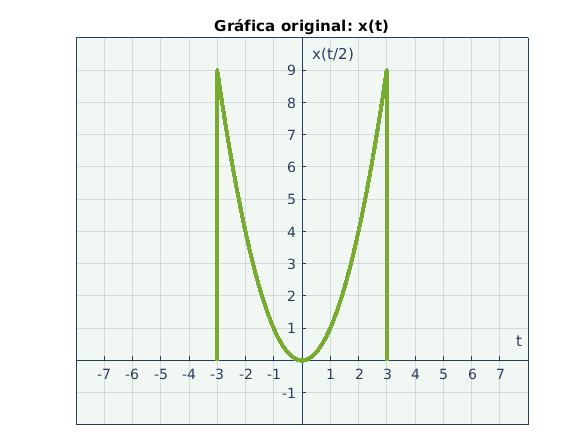

t=-3.01:.01:3.01;
x= @(t) (t.^2).*(-3<=t).*(t<=3);
Graficarpr4(t,x(t));
title("Gráfica original: x(t)");

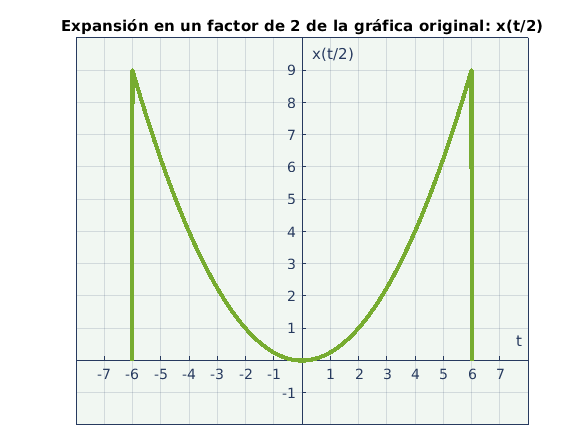

t=-6.01:.01:6.01;
Graficarpr4(t,x(t*(1/2)));
title("Expansión en un factor de 2 de la gráfica original: x(t/2)");
ylabel("x(t/2)");

Tal cual esperabamos la señal se expandió en un factor de 2 en el tiempo "ocupando el doble de espacio".

### Expansión discreto:

Igual que la compresión la expansión tiene un efecto similar en tiempo continuo y discreto, ya que la señal se expande en el tiempo y las alturas se grafican en un dominio determinado según el factor que se tenga (múltiplos de 2 para los ejemplos 1 y 2), pero en este caso hay un fenómeno interesante contrario al de la compresión, en vez de perderse datos, se generan "espacios vacíos" en el dominio que no tienen una altura definida, entonces la señal se muestra entera y además se generan esta clase de vacíos, para comprender esto tenemos un ejemplo:

#### Ejemplo 2:

Vamos en este caso a expandir la señal x[n]=n^3 en -2<n<2 en un factor de 2, lo que esto va a provocar es que la señal se alargue en el dominio de n creando huecos según sea el factor de compresión, en este caso dejará un hueco por valor ya que el factor es 2 y el dominio son los múltiplos de este, por la definición del argumento: x(n/2) se observa que si n no es múltiplo de 2, se evaluaría la función en decimales, pero como estamos graficando en tiempo discreto, esta evaluación no es válida "está indeterminada" por lo que el dominio solo son múltiplos del factor de expansión, y para los otros valores no hay altura generada

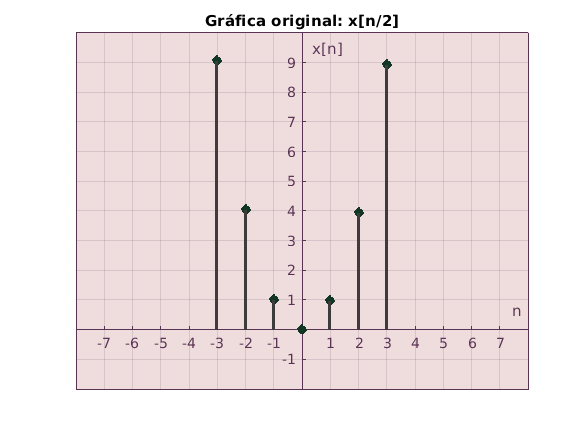

n=[-3.01:1:3.01];
x= @(n) (n.^2).*(n>=-4).*(n<=3);
Graficarpr3(n,x(n));
title("Gráfica original: x[n/2]");

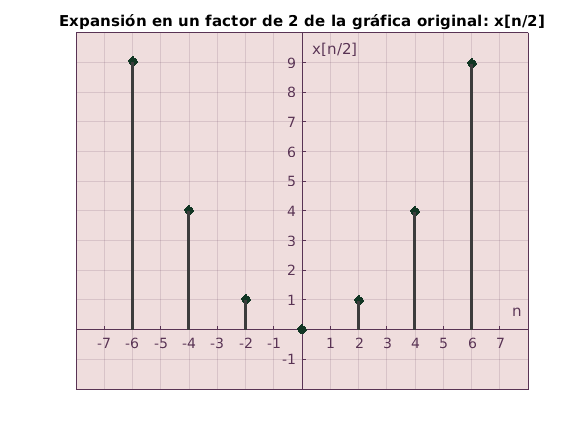

n=[-6.01:2:6.01];
Graficarpr3(n,x(n*(1/2)));
title("Expansión en un factor de 2 de la gráfica original: x[n/2]");
ylabel("x[n/2]");

Como se observa no hay pérdida de ningún dato, solamente se "recorren" en el tiempo y lo que se genera ahora no son pérdidas, sino vacantes, hay espacios con valores sin asignar y esto se soluciona de varias formas, 3 de las mas comunes son:

- Rellenar con ceros los huecos generados por la expansión.

- Usar algún método de interpolación para determinar las alturas que faltan con las ya conocidas.

- Dejar indeterminado el comportamiento de la función en los puntos donde se generan estos huecos.

MATLAB por defecto "soluciona" el problema interpolando, o en este caso, calculando la altura de todos los puntos de la función, por eso es que en valores como 3 o -5 donde no debería haber definición, si observamos un valor de la función cuando ponemos que t avance de 1 en 1 es decir que no ponemos un rango delimitado por los múltiplos de nuestro factor de expansión:

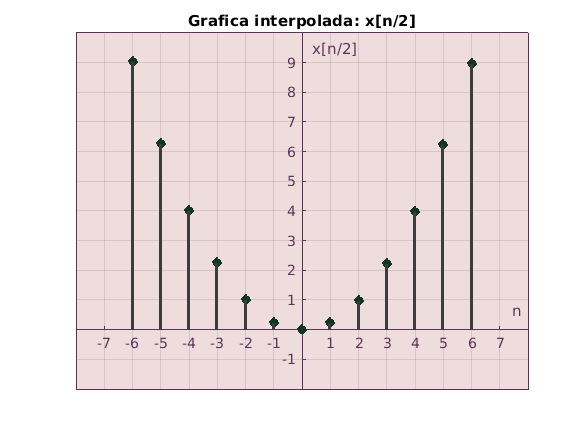

n=[-6.01:1:6.01];
Graficarpr3(n,x(n*(1/2)));
title("Grafica interpolada: x[n/2]");
ylabel("x[n/2]");

Bibliografía:

**Modern Digital and Analog Communication Systems**

B. P. Lathi, et. al. Linear Systems and Signals. Oxford University Press; 2 edition (2005). Para consultarlo da click aqui: [Libro Lathi](http://gen.lib.rus.ec/book/index.php?md5=16cb95a2877b2e5d2183067410bd7157)

Conceptos Básicos de procesamiento digital de señales. [Enlace a la lectura](http://odin.fi-b.unam.mx/labdsp/files/libros/conceptos.pdf) consultado el 27/02/2020 a las 21:04 hrs.

## Problema 1:

Para la señal mostrada en la (Figura 1) grafica las siguientes señales:

a) $x\left\lbrack -n\right\rbrack$

b) $x\left\lbrack n+6\right\rbrack$

c) $x\left\lbrack n-6\right\rbrack$

d) $x\left\lbrack 3n\right\rbrack$

e) $x\left\lbrack \frac{n}{3}\right\rbrack$

f) $x\left\lbrack 3-n\right\rbrack$

### Original $x\left\lbrack n\right\rbrack$

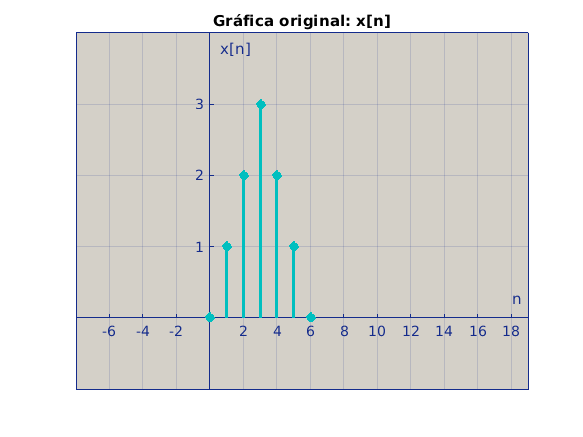

n=0:1:6;
x= @(n) n.*(n>=0).*(n<=3)+(-n+6).*(n>3).*(n<=6);
Graficarpr5(n,x(n));

###  Inciso a)

invertimos en el tiempo es decir, evaluamos en -n: $x\left\lbrack -n\right\rbrack$

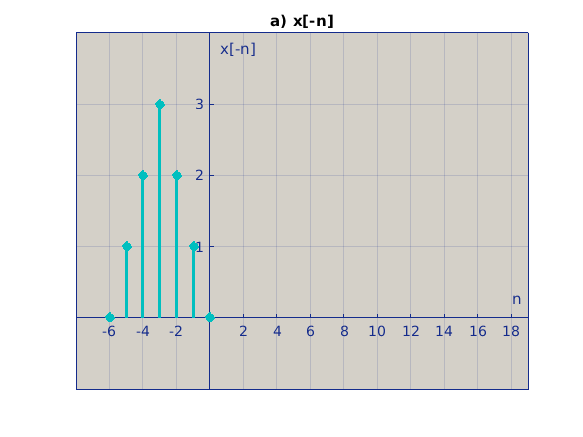

Graficarpr5(-n,x(n));
title("a) x[-n]");
ylabel("x[-n]");

###  Inciso b)

Trasladamos la señal original 6 unidades a la izquierda (adelantamos en el tiempo), evaluamos en n+6: $x\left\lbrack n+6\right\rbrack$

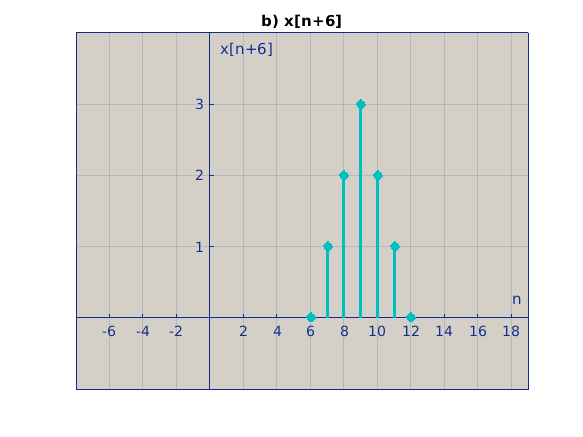

Graficarpr5(n+6,x(n));
title("b) x[n+6]");
ylabel("x[n+6]");

### Inciso c)

Trasladamos la señal original 6 unidades a la derecha (atrasamos en el tiempo), evaluamos en n-6: $x\left\lbrack n-6\right\rbrack$

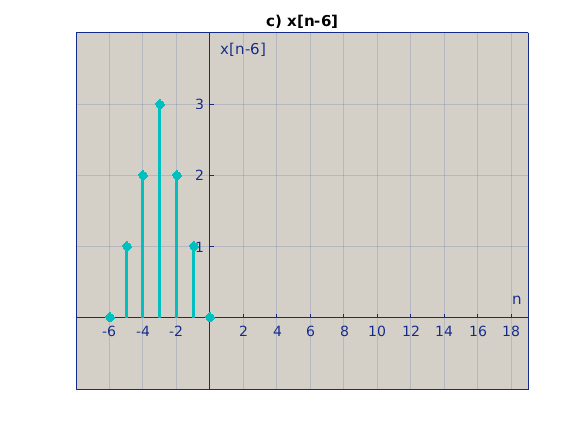

Graficarpr5(n-6,x(n));
title("c) x[n-6]");
ylabel("x[n-6]");

### Inciso d)

Comprimimos la señal en un factor de 3 (perdemos datos), evaluamos en 3n: $x\left\lbrack 3n\right\rbrack$

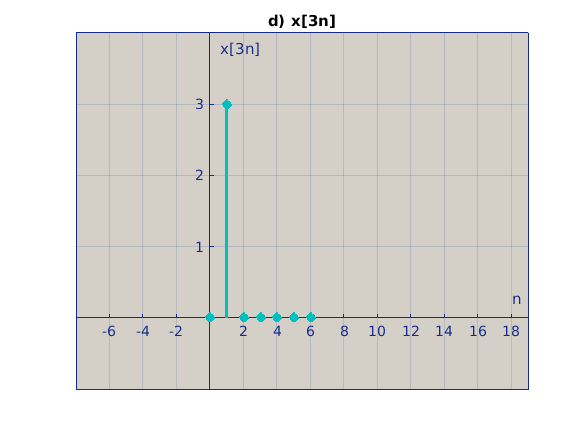

Graficarpr5(n,x(3*n));
title("d) x[3n]");
ylabel("x[3n]");

### Inciso e)

Expandimos la señal en un factor de 3, en este caso se generan "espacios vacios" con alturas sin asignar, y la señal esta completa: $x\left\lbrack \frac{n}{3}\right\rbrack$

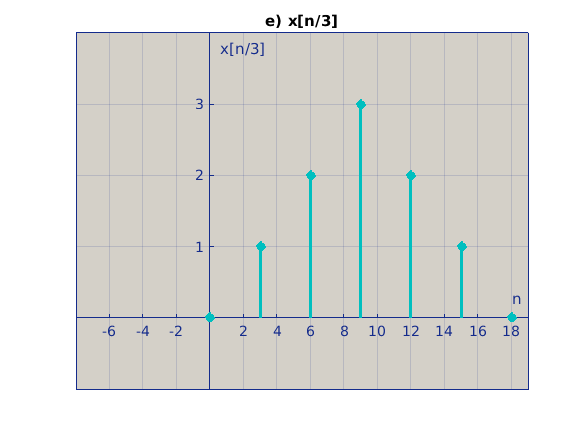

Graficarpr5(3*n,x(n));
title("e) x[n/3]");
ylabel("x[n/3]");

### Inciso f)

Trasladamos y escalamos la señal, en este caso trasladamos 3 unidades a la izquierda y luego la invertimos en el tiempo: $x\left\lbrack 3-n\right\rbrack$

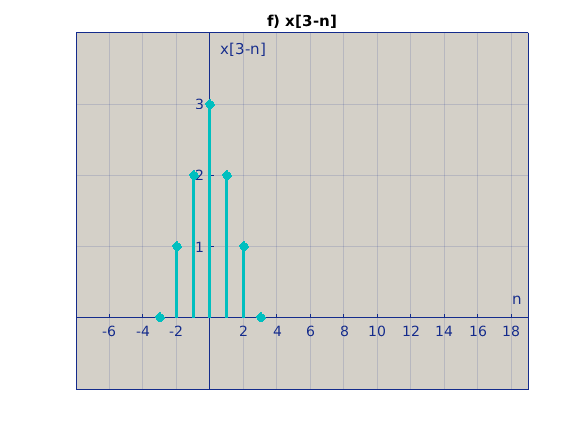

Graficarpr5(3-n,x(n));
title("f) x[3-n]");
ylabel("x[3-n]");

## Problema 2:

Los conceptos de funciones pares e impares para señales en tiempo discreto son idénticos a los de tiempo continuo vistos en clase. Usando dichos conceptos, encontrar la parte par e impar de las siguientes señales y graficarlas:

- 
$$u\left\lbrack n\right\rbrack$$


- 
$$\textrm{nu}\left\lbrack n\right\rbrack$$


- 
$$\textrm{sen}\left(\frac{\pi n}{4}\right)$$


- 
$$\cos \left(\frac{\pi n}{4}\right)$$


Parte par de una función: $x_p \left\lbrack n\right\rbrack =\frac{\left(x\left\lbrack n\right\rbrack +x\left\lbrack -n\right\rbrack \right)}{2}$

Parte impar de una función: $x_i \left\lbrack n\right\rbrack =\frac{\left(x\left\lbrack n\right\rbrack -x\left\lbrack -n\right\rbrack \right)}{2}$

Usando esos conceptos tenemos que:

### a)

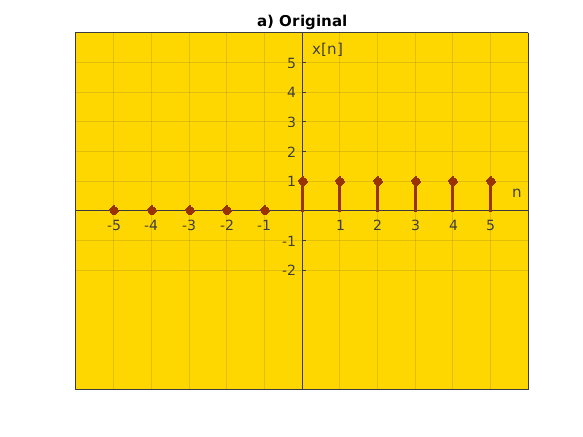

func1='1*(n>=0)';
n=[-5:1:5];
graficanenr (n,func1);

Para la función par hacemos: $u\left\lbrack n\right\rbrack +u\left\lbrack -n\right\rbrack$

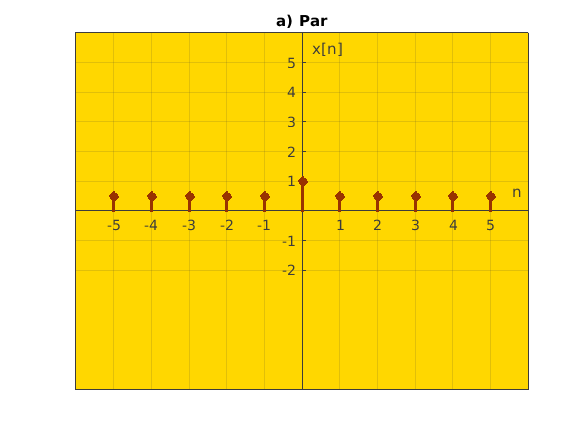

funcpar1='(1/2)*(1*(n>=0)+1*(-n>=0))';
graficanenr (n,funcpar1);
title ('a) Par');

Para la función impar hacemos: $u\left\lbrack n\right\rbrack -u\left\lbrack -n\right\rbrack$

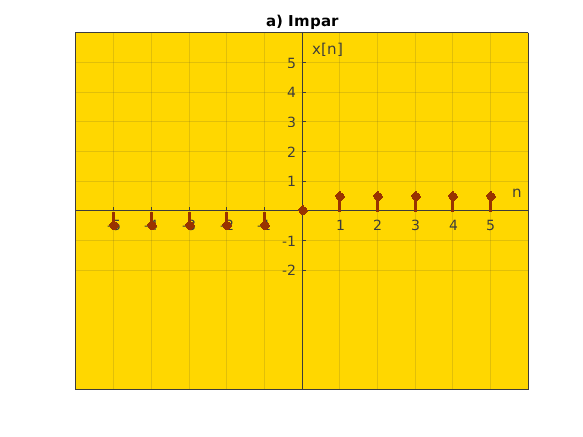

funcimpar1='(1/2)*(1*(n>=0)-1*(-n>=0))';
graficanenr (n,funcimpar1);
title ('a) Impar');

### b) 

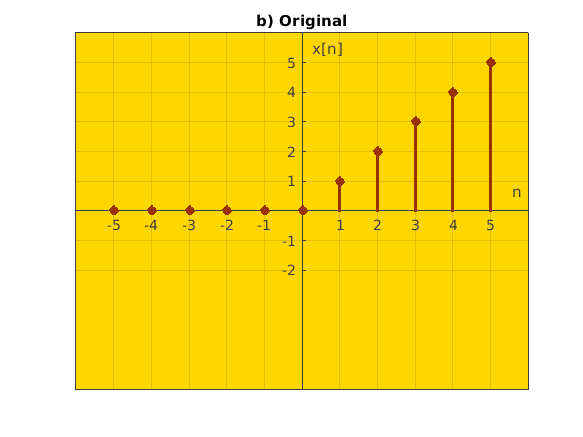

func2='n.*(n>=0)';
n=[-5:1:5];
graficanenr (n,func2);
title ('b) Original');

Para la función par hacemos: $\textrm{nu}\left\lbrack n\right\rbrack +\left(-\textrm{nu}\left\lbrack -n\right\rbrack \right)$

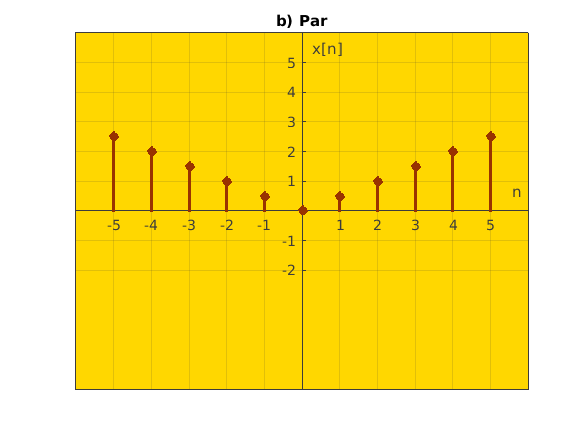

funcpar2='(1/2)*(n.*(n>=0)-n.*(-n>=0))';
graficanenr (n,funcpar2);
title ('b) Par');

Para la función impar hacemos: $\textrm{nu}\left\lbrack n\right\rbrack -\left(-\textrm{nu}\left\lbrack -n\right\rbrack \right)$

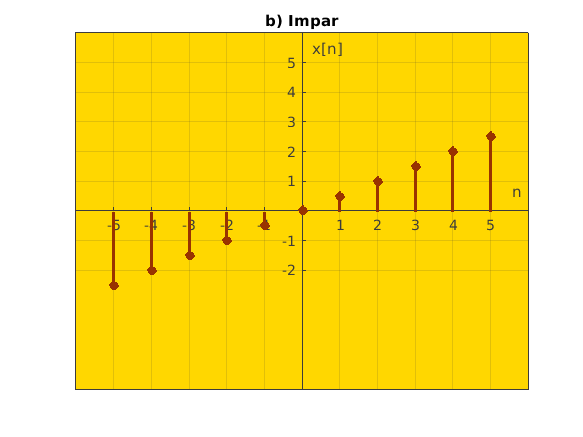

funcimpar2='(1/2)*(n.*(n>=0)+n.*(-n>=0))';
graficanenr (n,funcimpar2);
title ('b) Impar');

### c)

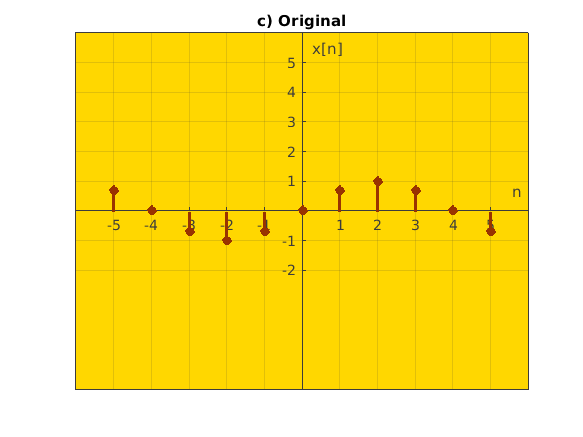

func3='sin((pi*n)/4)';
n=[-5:1:5];
graficanenr (n,func3);
title ('c) Original');

Para la función par hacemos: $\textrm{sen}\left(\frac{\pi n}{4}\right)+\textrm{sen}\left(\frac{-\pi n}{4}\right)$

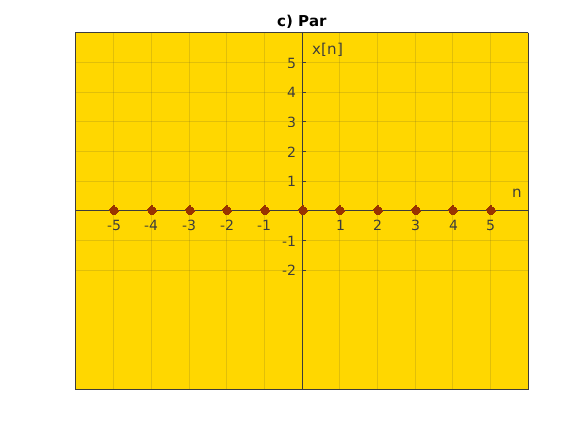

funcpar3='(1/2)*(sin((pi*n)/4)+sin((-pi*n)/4))';
graficanenr (n,funcpar3);
title ('c) Par');

Para la función impar hacemos: $\textrm{sen}\left(\frac{\pi n}{4}\right)-\textrm{sen}\left(\frac{-\pi n}{4}\right)$

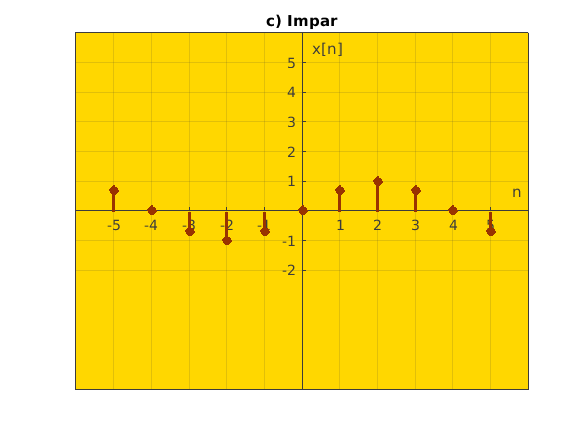

funcimpar3='(1/2)*(sin((pi*n)/4)-sin((-pi*n)/4))';
graficanenr (n,funcimpar3);
title ('c) Impar');

### d)

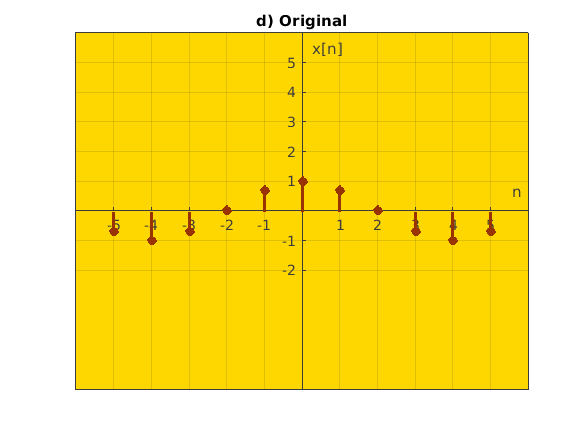

func4='cos((pi*n)/4)';
n=[-5:1:5];
graficanenr (n,func4);
title ('d) Original');

Para la función par hacemos: $\cos \left(\frac{\pi n}{4}\right)+\cos \left(\frac{-\pi n}{4}\right)$

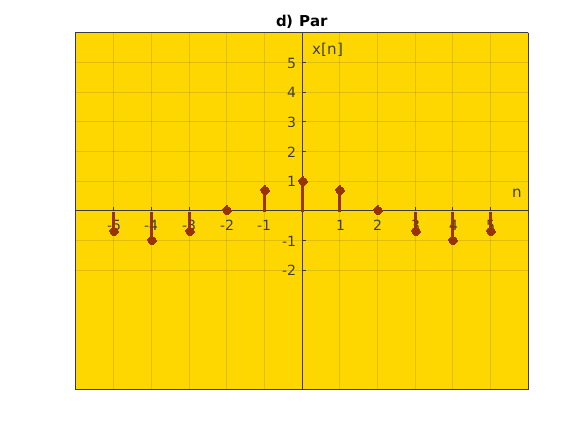

funcpar4='(1/2)*(cos((pi*n)/4)+cos((-pi*n)/4))';
graficanenr (n,funcpar4);
title ('d) Par');

Para la función impar hacemos: $\cos \left(\frac{\pi n}{4}\right)-\cos \left(\frac{-\pi n}{4}\right)$

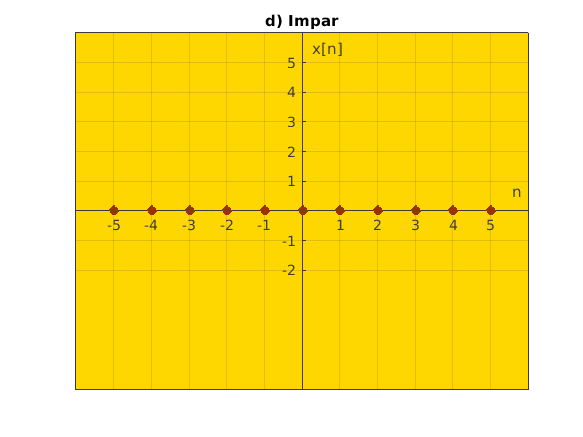

funcimpar4='(1/2)*(cos((pi*n)/4)-cos((-pi*n)/4))';
graficanenr (n,funcimpar4);
title ('d) Impar');

## Problema 3:

La captura de la aplicación realizada siguiendo los criterios establecidos para graficar señales en tiempo discreto se muestra a continuación: